# PHYS 361: Logical Operations and Decision Branching

## **Logical Operations**

Logical operations test whether statement is true or false.  Then the code can make a decision based on that.

The relational operators in MATLAB are:

<   less than

> greater than

<= less than or equal to 

>= greater than or equal to

== equal to

~= not equal to

The logical operators in MATLAB are:

&   AND

|    OR

~  NOT

You can use these operators to test whether or not things are true or false.  See the following code for some examples,

3 == 3          %Is 3 equal to 3?

ans = logical
   1


3 ~= 3          %Is 3 not equal to 3

ans = logical
   0


Note that the output is 1 if the relationship is true and 0 if the relationship is false.

## The order of logical operations

*The order that logical operations will be evaluated in MATLAB:*

1.Parentheses

2.~

3.Multiplication/Division

4.Addition/Subtraction

5.Relational operators (e.g. >,==,..)

6.Logical AND (&)

7.Logical OR (|)

3 == 3 & 3==4        %Is 3 equal to 3 AND 3 equal to 4? (false, 0)

ans = logical
   0


3 == 3 | 3==4        %Is 3 equal to 3 OR 3 equal to 4? (true,1)

ans = logical
   1


3 == 3  & 8> 3         %Is 3 equal to 3 AND 8 greater than 3? (true,1)

ans = logical
   1


~(3==3)              %Is it not true that 3 is equal to 3? (false,0) 

ans = logical
   0


You can also test values accross an array.

%All test are done element by element, results in an array of 1's and 0's (trues and falses)
array1 = [3 3 3 4 5]

array1 =      3     3     3     4     5


array2 = [3 4 3 7 5]

array2 =      3     4     3     7     5



array1 == array2

ans = 1×5 logical array
   1   0   1   0   1


array2 > array1

ans = 1×5 logical array
   0   1   0   1   0


sum(array2 > array1)

ans = 2


array2 >= array1

ans = 1×5 logical array
   1   1   1   1   1


## Logic Table

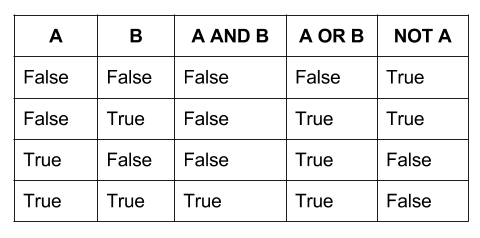

# Decision Branching

## If Statements

The `If` command is a conditional statement that allows MATLAB to make a decision regarding what commands to run based on some input.  

Below is an example of a basic `if` statement:

clear all;

planet = 'Mars'

planet = 'Mars'


if (strcmp(planet,'Mars'))
    gravity = 3.711;
end

gravity

gravity = 3.7110

**Note**: We are comparing the string '`planet`' and to another string '`Mars`' using the function `strcmp` (short for string compare).

Notice, after the if-statement, gravity is set to the value appropriate for Mars.  If instead, we changed the string variable planet to 'Earth', gravity remains undefined.

## If-else Statements

Maybe I want to assume that if the planet is NOT Mars,  it is Earth.  See the code below:

clear all;

planet = 'bananas'

planet = 'bananas'


if (strcmp(planet,'Mars'))
    gravity = 3.711;
else
    gravity = 9.798;
end

gravity

gravity = 9.7980

Now, if you change the planet to Earth, or any other string, it will set gravity equal to the Earth value.

## If-elseif

That probably isn't quite right. I can make sure the intended planet is Earth with an `elseif` statement:

clear all;

planet = 'Mars'

planet = 'Mars'


if (strcmp(planet,'Mars'))
    gravity = 3.711;
elseif (strcmp(planet,'Earth'))
    gravity = 9.798;
end

gravity

gravity = 3.7110

Now, if you change the planet variable to something like 'Jupiter', none of the If-else statement conditions are met, and gravity remains undefined.

## Multiple If-elseif Statements

There is no limit to these types of statements, for example, here I can test for four different planets:

clear all;

planet = 'Mars'

planet = 'Mars'


if (strcmp(planet,'Mars'))
    gravity = 3.711;
elseif (strcmp(planet,'Earth'))
    gravity = 9.798;
elseif (strcmp(planet,'Saturn'))
    gravity = 10.44;
elseif (strcmp(planet,'Jupiter'))
    gravity = 24.79;
end

gravity

gravity = 3.7110

## Switch Statements

You could also use the switch statement, which identifies the variable being tested and presents possible cases. For example, I could rewrite the code above like this:

clear all;

planet = 'Neptune'

planet = 'Neptune'


switch planet
    case 'Mars'
        gravity = 3.711;
    case 'Earth'
        gravity = 9.798;
    case 'Saturn'
        gravity = 10.44;
    case 'Jupiter'
        gravity = 24.79;
    otherwise
        gravity = NaN;
end

gravity

gravity = NaN

The switch statement is easier to read, especially with indented formatting. The otherwise statement at the end is a catch-all if none of the above conditions are met. Finally, note that you still need an end statement. Try it out by changing the variable planet.